load('sizing')

%parameters from poster
W_S= 2973 %

W_S = 2973

C_cruise=295.1 %m/s

C_cruise = 295.1000

M_cruise=0.75

M_cruise = 0.7500

V_cruise=C_cruise*M_cruise %m/s

V_cruise = 221.3250

rho_cruise= 0.302748958

rho_cruise = 0.3027

W_cruise_W_total=0.842

W_cruise_W_total = 0.8420

Max_takeoff_weight=3740 %kg

Max_takeoff_weight = 3740

%mu_cruise=2.969*10^(-7)
mu_cruise=1.45*10^(-5)

mu_cruise = 1.4500e-05

character_c=0.6096

character_c = 0.6096

CL_design_cruise=( (W_cruise_W_total)*(W_S) )/ (0.5*rho_cruise*V_cruise^2)

CL_design_cruise = 0.3376


% L_over_D=Cl/cd;
% plot( Alpha, Cl)
% ylabel('Cl')
% xlabel('alpha')
% [CL_Alpha_curve, gof] = CL_ALPHA_FIT(Alpha, Cl)
% 
% Cl_design=CL_Alpha_curve(4.25)



% Cl_max=max(Cl)



%mach
sweep_angle=27.106

sweep_angle = 27.1060

M_DD=0.77

M_DD = 0.7700

M_DD_Eff=M_DD*sqrt(cosd(sweep_angle))

M_DD_Eff = 0.7265

AR=7.8

AR = 7.8000

x=cosd(22)

x = 0.9272


Cl_design_a=(CL_design_cruise/(0.9*0.95))/cosd(sweep_angle)

Cl_design_a = 0.4436



Km=1.05

Km = 1.0500


%lambda_opt=0.45*(0.85)^(-0.036*sweep_angle)
lambda_opt=0.45*exp(-0.036*sweep_angle)

lambda_opt = 0.1696

lambda_min=0.2*(AR)^(0.25)*(cosd(sweep_angle))^2

lambda_min = 0.2648

SP=(Max_takeoff_weight*9.8)/(W_S) 

SP = 12.3283

struct.b = sqrt(AR*SP) 

b = 9.8062

lambda_opt=lambda_min

lambda_opt = 0.2648

struct.C_root= (2*12.34086)/(9.811*(1+lambda_opt))

C_root = 1.9890

struct.C_tip=0.51*C_root

C_tip = 1.0144

C_mean=(2/3) * C_root* ((1+lambda_opt+lambda_opt^2)/(1+lambda_opt))

C_mean = 1.3995


y_bar=(b/6)*((1+2*lambda_opt)/(1+lambda_opt))

y_bar = 1.9766


t_c= 0.3*cosd(sweep_angle)*((1-((5+M_DD_Eff^2)/(5+(Km-0.25*Cl_design_a)^2))^3.5)*((sqrt(1-M_DD_Eff^2)/M_DD_Eff^2)))^(2/3)

t_c = 0.1072


Re= (rho_cruise * V_cruise * C_mean )/ mu_cruise

Re = 6.4672e+06

twist=-3

twist = -3

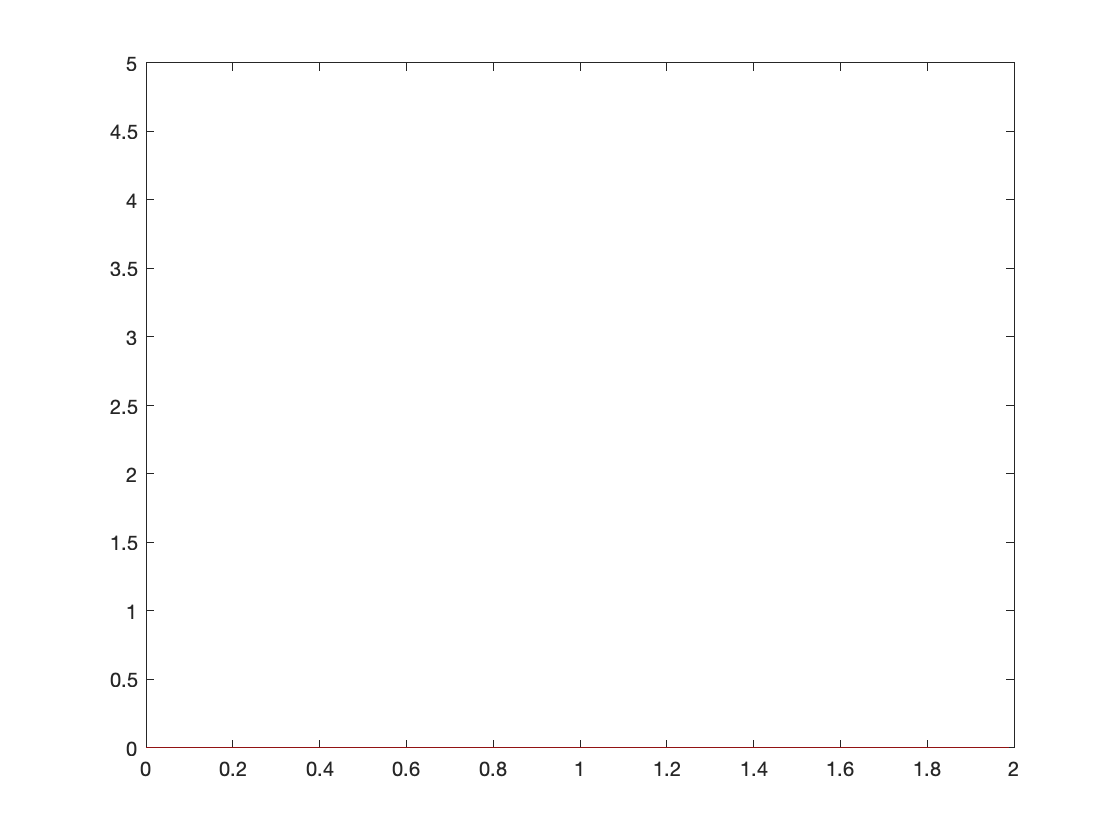


[phi_m] = sweep_angle(sweep_angle,0,0.25,AR,lambda_opt)
[fig] = horizontal_stab_plot(struct)


% i_w_mac=1
% i_w= (y_bar/(b/2))*twist + i_w_mac
alpha_0=-3

alpha_0 = -3

CL_cruise=0.4809

CL_cruise = 0.4809


Cl_alpha=(12--8)/(8.5--6.2)

Cl_alpha = 1.3605

i_w= (CL_cruise/Cl_alpha)+alpha_0 +0.4*twist

i_w = -3.8465




save('wing','wing.mat')


